% Time evolution for specific values of Oc
% cavity mode -  semi-classical approach!
echo off
clear all
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% DEFINING THE PARAMETERS FOR THIS SYSTEM (Hamiltonian): %%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Nat = 1;   % Number of atoms.
kappa = 1.0;

g = 10.0*kappa/sqrt(Nat);           % atom-field coupling: atomic transition 3<->1.
EM = sqrt(0.1)*kappa;          % probe field - the cavity mode -it'll be evaluated bellow!
Oc_list = [0.01, 0.1, 0.5, 1.0, 2.0]*kappa;           % Rabi freq. control field (pumping - atomic transition 2 <-> 3.
D1 = 0.0;          % Detuning between the atom and the cavity mode (Delta1).
D2 = 0.0;          % Detuning between the atom and the control field (Delta2).
Dp = 0.01*kappa;   % Detuning between the probe field and the cavity mode.
%%%%%%%% DEFINING THE DISSIPATIVE PARAMETERS - Decay rates: %%%%%%%%%%%%%%
Gamma31 = 0.5;     % Decay rate from the level 3 to level 1.
Gamma32 = 0.5;     % Decay rate from the level 3 to level 2.
gamma2  = 0.0;    % Dephasing rate -  level 2.
gamma3  = 0.0;    % Dephasing rate -  level 3.

% Varying Parameters
nsteps = 501;
TM = 2100;
t0 = 0;
tspan = linspace(t0, TM, nsteps)

tspan = 	1.0e+03 *

         0    0.0042    0.0084    0.0126    0.0168    0.0210    0.0252    0.0294    0.0336    0.0378    0.0420    0.0462    0.0504    0.0546    0.0588    0.0630    0.0672    0.0714    0.0756    0.0798    0.0840    0.0882    0.0924    0.0966    0.1008    0.1050    0.1092    0.1134    0.1176    0.1218    0.1260    0.1302    0.1344    0.1386    0.1428    0.1470    0.1512    0.1554    0.1596    0.1638    0.1680    0.1722    0.1764    0.1806    0.1848    0.1890    0.1932    0.1974    0.2016    0.2058


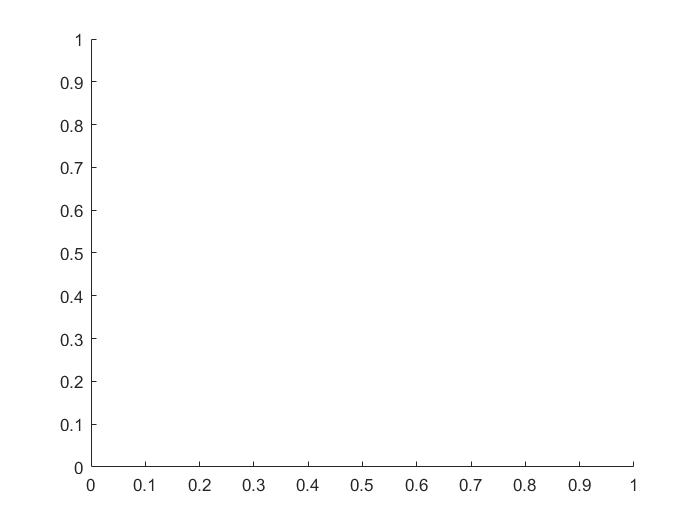


opts = odeset('RelTol',1e-10,'AbsTol',1e-10);
y0 = [0 0 0 0 0 0 0 0 Nat 0 0];   % Initial condition: <sigma_ 11> = 1. -> <S11> = N*<sigma_ 11>.
hold on;


%%%%%%%% First loop: Varying control rabi frequency %%%%%%%%%%
for k = 1:length(Oc_list)
    
    Oc = Oc_list(k);  
    [t,Y] = ode45(@(t,y) semiclassical(t0, g, EM, Oc, D1, D2, Dp, Gamma31, Gamma32, gamma2, gamma3, kappa, t, y), tspan, [y0], opts);
    a = Y(:,1);
    a_dag = Y(:,2);
    transmission(k,:) = (a .* a_dag)/(4*(EM/kappa)^2);
    fprintf('%d%%...',101.0*k/5);   %progress
end

2.020000e+01%...4.040000e+01%...6.060000e+01%...8.080000e+01%...101%...

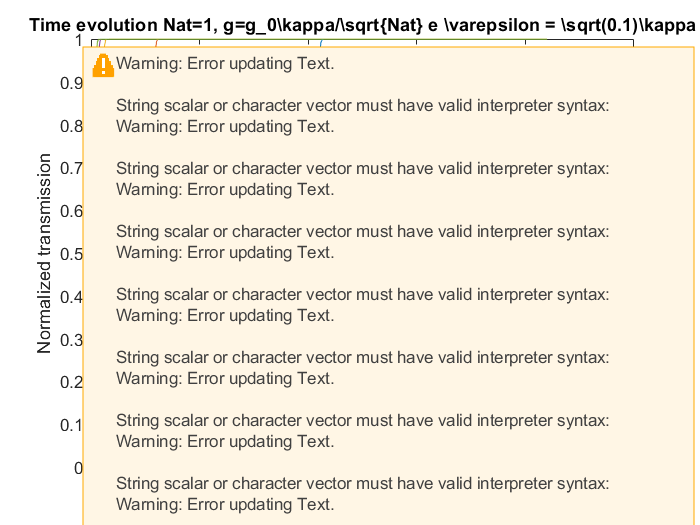


f2 = figure; p2 = plot(tspan, transmission);

title('Time evolution Nat=1, g=g_0\kappa/\sqrt{Nat} e \varepsilon = \sqrt(0.1)\kappa')
legend('\Omega_C=0.01\kappa','\Omega_C=0.1\kappa','\Omega_C=0.5\kappa','\Omega_C=1.0\kappa','\Omega_C=2.0\kappa')
xlabel('t\kappa')
ylabel('Normalized transmission')

dlmwrite('C:\Users\lucas\Desktop\Semiclassical\integration\MatLab\semiclassical_intML_TimeEvolution_Nat1_g10_ep01.csv', [tspan(:,:),transmission(1,:),transmission(2,:),transmission(3,:),transmission(4,:),transmission(5,:)]);
hold off;

% System of differential equations for N atoms interacting with a cavity
% mode. However, considering a semi-classical approach, i.e., the cavity
% mode is classical. So, we solve the Maxwell-Bloch equations!


function dy = semiclassical(t0, g, EM, Oc, D1, D2, Dp, Gamma31, Gamma32, gamma2, gamma3, kappa, t, y)

    dy = zeros(11,1);    % a column vector
    dy(1) = 1i*(Dp+1i*(kappa/2))*y(1) - 1i*EM - 1i*g*y(5);    % <a>
    dy(2) = -1i*(Dp-1i*(kappa/2))*y(2) + 1i*EM + 1i*g*y(6);  % <a'>
        
    dy(3) = 1i*(Dp-(D1-D2)+1i*(gamma2/2))*y(3) +1i*g*y(1)*y(8) -1i*Oc*y(5);  % <S12>
    dy(4) = -1i*(Dp-(D1-D2)-1i*(gamma2/2))*y(4) -1i*g*y(2)*y(7) +1i*Oc*y(6); % <S21>
        
    dy(5) = 1i*(Dp-D1+(1i/2)*(Gamma31+Gamma32+gamma3))*y(5) -1i*g*y(1)*(y(9)-y(11)) - 1i*Oc*y(3);  % <S13>
    dy(6) = -1i*(Dp-D1-(1i/2)*(Gamma31+Gamma32+gamma3))*y(6) +1i*g*y(2)*(y(9)-y(11)) + 1i*Oc*y(4); % <S31>
        
    dy(8) = 1i*(D2+(1i/2)*(Gamma31+Gamma32+gamma2+gamma3))*y(8) +1i*g*y(2)*y(3)+1i*Oc*(y(10)-y(11));  % <S32>
    dy(7) = -1i*(D2-(1i/2)*(Gamma31+Gamma32+gamma2+gamma3))*y(7) -1i*g*y(1)*y(4)-1i*Oc*(y(10)-y(11)); % <S23>
        
    dy(9) = 1i*g*y(1)*y(6)-1i*g*y(2)*y(5)+2*(Gamma31/2)*y(11); % <S11>
    dy(10) = -1i*Oc*(y(7)-y(8))+2*(Gamma32/2)*y(11);           % <S22>
    dy(11) = -(1i*g*y(1)*y(6)-1i*g*y(2)*y(5)+2*(Gamma31/2)*y(11))-(-1i*Oc*(y(7)-y(8))+2*(Gamma32/2)*y(11)); % <S33>
    
end